# Uniform sampling

## Author(s): **Hulda S. Haraldsdóttir and German A. Preciat Gonzalez, **Systems Biochemistry Group, University of Luxembourg.

## Reviewer(s): 

## INTRODUCTION

The flux space $\Omega$ for a given set of biochemical and physiologic constraints is represented by: 


$$\Omega = \{v \mid Sv=b; l \leq v\leq u\}$$


where $v$ represents feasible flux vectors,  $S\in\mathcal{Z}^{m\times n}$ the stoichiometric matrix, while $l$ and $u$ are lower and upper bounds on fluxes. These criteria still allow a wide range of admissible flux distributions which, in FBA are commonly further restricted by introducing an objective to optimise, transforming the question of admissible fluxes into an FBA problem of the form


$$\begin{array}{ll}
\min\limits _{v} & c^{T}v\\
\text{s.t.} & Sv=b,\\
 & l\leq v\leq u,
\end{array}$$


where $c$ is a linear biological objective function (biomass, ATP consumption, HEME production, etc.). Even under these conditions there is commonly a range of optimal flux distributions, which can be investigated using flux variability analysis. If the general capabilities of the model are of interest, however, uniform sampling of the entire flux space $\Omega$ is able to provide an unbiased characterization, and therefore, can be used to investigate the biochemical networks. It requires collecting a statistically meaningful number of flux distributions uniformly spread throughout the whole flux space and then analysing their properties. There are three basic steps to perform a uniform sampling for a set of feasible fluxes:

- Define the flux space to be sampled from physical and biochemical constraints

- Randomly sample the defined flux space based on uniform statistical criteria

- If is necessary, section the flux space according to post-sampling.

In COBRA v3 there are three different sampling algorithms: coordinate hit-and-run with rounding (CHRR), artificial centring hit-and-run (ACHR) and the minimum free energy (MFE). In this tutorial, we will use the CHRR algorithm [1] to uniformly sample a high dimensionally constraint-based model of the differentiation of induced pluripotent stem cells to dopaminergic neurons (iPSC_dopa). The algorithm consists of rounding the anisotropic flux space  Ω using a maximum volume ellipsoid algorithm [4] and then performs a uniform sampling based on the provably efficient hit-and-run random walk [5]. Below is a high-level illustration of the process to uniformly sample a random metabolic flux vector $v$ from the set $\Omega$ of all feasible metabolic fluxes (grey). **1)** Apply a rounding transformation $T$ to $\Omega$. The transformed set $\Omega \prime =T\Omega \text{ }$ is such that its maximal inscribed ellipsoid (blue) approximates a unit ball. **2)** Take $q$ steps of coordinate hit-and-run. At each step, i) pick a random coordinate direction $e_i$, and ii) move from current point $v\prime_k \in \Omega \prime$ to a random point $v\prime_{k+1} \in \Omega \prime$ along $v\prime_k +\alpha e_i \cap \Omega \prime$. **3)** Map samples back to the original space by applying the inverse transformation, e.g., $v_k =T^{−1} v\prime_k$.

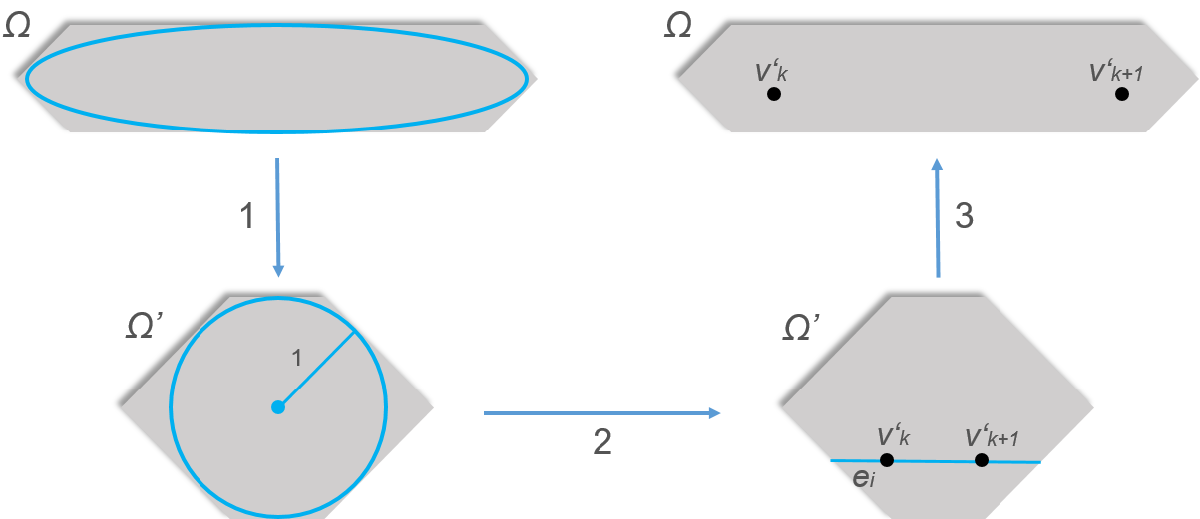

## Equipment setup

 changeCobraSolver('gurobi');


 > Gurobi interface added to MATLAB path.


## Modelling

We will investigate ATP energy production with limited and unlimited oxygen uptake, following closely the flux balance analysis (FBA) tutorial published with [3].

We start by loading the model with its flux bounds and the objective function (ATP demand reaction). We set the maximum glucose uptake rate to 18.5 mmol/gDW/hr. To explore the entire space of feasible steady state fluxes we also remove the cellular objective.

load('data/iPSC_DA.mat','modelUptClosed') % Load the model
model = modelUptClosed;
model = changeRxnBounds(model, 'EX_glc(e)', -18.5, 'l');
model.c = 0 * model.c; % clear the objective

We allow unlimited and limited oxygen uptake in the models creating two distinct models based on the input model.

unlimitedOx = changeRxnBounds(model, 'EX_o2(e)', -1000, 'l');
limitedOx = changeRxnBounds(model, 'EX_o2(e)', -4, 'l');

## Flux variability analysis

Flux variability analysis (FVA) returns the minimum and maximum possible flux through every reaction in a model.

[minUn, maxUn] = fastFVA(unlimitedOx, 100);

 > The CPLEX version has been determined as 1271.

-- Warning:: You may only ouput 4, 7 or 9 variables.

 >> Solving Model.S. (uncoupled) 
 >> The number of arguments is: input: 2, output 2.
 >> Size of stoichiometric matrix: (2825,4195)
 >> All reactions are solved (4195 reactions - 100%).
 >> 0 reactions out of 4195 are minimized (0.00%).
 >> 0 reactions out of 4195 are maximized (0.00%).
 >> 4195 reactions out of 4195 are minimized and maximized (100.00%).
 

 >> The number of reactions retrieved is 4195
 >> Log files will be stored at /Users/sxc554/Documents/Research/Research/COBRA/cobratoolbox/src/analysis/FVA/fastFVA/logFiles
 -- Start time:     Wed Jul 12 01:06:27 2017
 >> #Task.ID = 1; logfile: cplexint_logfile_1.log

 -- Warning:: The optPercentage is higher than 90. The solution process might take longer than you expect.

        -- Minimization (iRound = 0). Number of reactions: 4195.
        -- Maximization (iRound = 

[minLim, maxLim] = fastFVA(limitedOx, 100);

 > The CPLEX version has been determined as 1271.

-- Warning:: You may only ouput 4, 7 or 9 variables.

 >> Solving Model.S. (uncoupled) 
 >> The number of arguments is: input: 2, output 2.
 >> Size of stoichiometric matrix: (2825,4195)
 >> All reactions are solved (4195 reactions - 100%).
 >> 0 reactions out of 4195 are minimized (0.00%).
 >> 0 reactions out of 4195 are maximized (0.00%).
 >> 4195 reactions out of 4195 are minimized and maximized (100.00%).
 

 >> The number of reactions retrieved is 4195
 >> Log files will be stored at /Users/sxc554/Documents/Research/Research/COBRA/cobratoolbox/src/analysis/FVA/fastFVA/logFiles
 -- Start time:     Wed Jul 12 01:10:53 2017
 >> #Task.ID = 1; logfile: cplexint_logfile_1.log

 -- Warning:: The optPercentage is higher than 90. The solution process might take longer than you expect.

        -- Minimization (iRound = 0). Number of reactions: 4195.
        -- Maximization (iRound = 

FVA predicts faster maximal ATP production with unlimited and limited oxygen uptake conditions.

ATP = 'DM_atp_c_';  % Identifier of the ATP demand reaction
ibm = find(ismember(model.rxns, ATP));  % column index of the ATP demand reaction
fprintf('Max. ATP energy production with an unlimited oxygen uptake: %.4f/h.\n', maxUn(ibm));

Max. ATP energy production with an unlimited oxygen uptake: 152.2120/h.


fprintf('Max. ATP energy production with a limited oxygen uptake: %.4f/h.\n\n', maxLim(ibm));

Max. ATP energy production with a limited oxygen uptake: 15.5993/h.



An overall comparison of the FVA results can be obtained by computing the [Jaccard index](https://en.wikipedia.org/wiki/Jaccard_index) for each reaction. The Jaccard index is here defined as the ratio between the intersection and union of the flux ranges in the unlimitedOx and limitedOx models. A Jaccard index of 0 indicates completely disjoint flux ranges and a Jaccard index of 1 indicates completely overlapping flux ranges. The mean Jaccard index gives an indication of the overall similarity between the models.

J = fvaJaccardIndex([minUn, minLim],[maxUn, maxLim]);
fprintf('Mean Jaccard index = %.4f.\n', mean(J));

Mean Jaccard index = 0.6810.


To visualise the FVA results, we plot the flux ranges as errorbars, with reactions sorted by the Jaccard index.

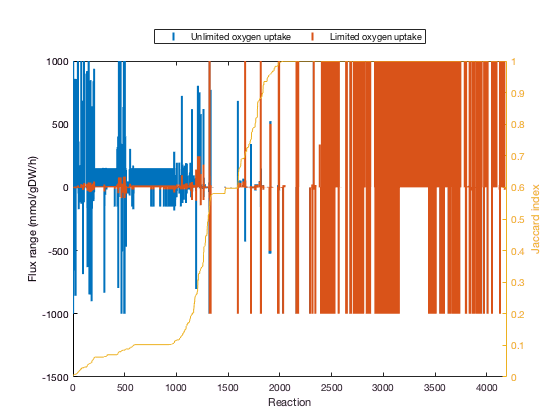

E = [(maxUn - minUn)/2 (maxLim - minLim)/2];
Y = [minUn minLim] + E;
X = [(1:length(Y)) - 0.1; (1:length(Y)) + 0.1]';

[~, xj] = sort(J);

f1 = figure;
if strcmp(version('-release'), '2016b')
    errorbar(X, Y(xj, :), E(xj, :), 'linestyle', 'none', 'linewidth', 2, 'capsize', 0);
else
    errorbar(X, Y(xj, :), E(xj, :), 'linestyle', 'none', 'linewidth', 2);
end
set(gca, 'xlim', [0, length(Y) + 1])
legend('Unlimited oxygen uptake', 'Limited oxygen uptake', 'location', 'northoutside', ...
       'orientation', 'horizontal')
xlabel('Reaction')
ylabel('Flux range (mmol/gDW/h)')

yyaxis right
plot(J(xj))
ylabel('Jaccard index')

## Sampling

CHRR can be called via the function `sampleCbModel`. The main inputs to `sampleCbModel` are a COBRA model structure, the name of the selected sampler and a parameter struct that controls properties of the sampler used. In the instance of CHRR, two parameters are important: the sampling density (`nStepsPerPoint)` and the number of samples (`nPointsReturned). `The total length of the random walk is `nStepsPerPoint*nPointsReturned`. The time it takes to run the sampler depends on the total length of the random walk and the size of the model [1]. However, using sampling parameters that are too small will lead to invalid sampling distributions, e.g.,

options.nStepsPerPoint = 1;
options.nPointsReturned = 100;

An additional on/off parameter (`toRound`) controls whether or not the polytope is rounded. Rounding large models can be slow but is strongly recommended for the first round of sampling. Below we show how to get around this step in subsequent rounds. 

options.toRound = 1;

The method outputs two results. First, the model used for sampling (in case of `toRound = 1` this would be the rounded model), and second, the samples generated. To sample the unlimitedOx and limitedOx iPSC_dopa models, run,

[P_un, X1_un] =  sampleCbModel(unlimitedOx, [], [], options);

Checking for width 0 facets...
Starting parallel pool (parpool) using the 'local' profile ... connected to 2 workers.
Parallel computation initialized
 > The CPLEX version has been determined as 1271.

-- Warning:: You may only ouput 4, 7 or 9 variables.

 >> Solving Model.S. (uncoupled) 
 >> The number of arguments is: input: 2, output 2.
 >> Size of stoichiometric matrix: (2825,4195)
 >> All reactions are solved (4195 reactions - 100%).
 >> 0 reactions out of 4195 are minimized (0.00%).
 >> 0 reactions out of 4195 are maximized (0.00%).
 >> 4195 reactions out of 4195 are minimized and maximized (100.00%).

 -- Starting to loop through the 2 workers. -- 

 -- The splitting strategy is 0. -- 

----------------------------------------------------------------------------------

----------------------------------------------------------------------------------
--  Task Launched // TaskID: 1 / 2 (LoopID = 2) <> [2099, 4195] / [2825, 4195].
 >> Number of reactions given to the worker: 2097 

Now in 1403 dimensions after restricting
Removed 7072 zero rows
Rounding...
Iteration 1: reg=1.0e-04, ellipsoid vol=0.0e+00, longest axis=4.6e+01, shortest axis=2.8e-04, x0 dist to bdry=8.6e-04, time=4.9e+02 seconds
Iteration 2: reg=1.0e-05, ellipsoid vol=Inf, longest axis=5.8e+03, shortest axis=7.2e-01, x0 dist to bdry=1.2e+00, time=6.2e+02 seconds
Iteration 3: reg=1.0e-06, ellipsoid vol=Inf, longest axis=1.7e+04, shortest axis=7.1e-01, x0 dist to bdry=1.2e+00, time=5.2e+02 seconds
Stopped making progress, stopping and restarting.
Iteration 4: reg=1.0e-07, ellipsoid vol=Inf, longest axis=1.6e+04, shortest axis=6.0e-01, x0 dist to bdry=1.2e+00, time=1.2e+03 seconds
Stopped making progress, stopping and restarting.
Iteration 5: reg=1.0e-08, ellipsoid vol=Inf, longest axis=4.8e+04, shortest axis=3.7e-01, x0 dist to bdry=1.2e+00, time=9.1e+02 seconds
  Converged!
Iteration 6: reg=1.0e-09, ellipsoid vol=Inf, longest axis=3.2e+04, shortest axis=2.5e-01, x0 dist to bdry=1.2e+00, time=3.3e+03

[P_lim, X1_lim] = sampleCbModel(limitedOx, [], [], options);

Checking for width 0 facets...


Starting parallel pool (parpool) using the 'local' profile ... connected to 2 workers.
Parallel computation initialized
 > The CPLEX version has been determined as 1271.

-- Warning:: You may only ouput 4, 7 or 9 variables.

 >> Solving Model.S. (uncoupled) 
 >> The number of arguments is: input: 2, output 2.
 >> Size of stoichiometric matrix: (2825,4195)
 >> All reactions are solved (4195 reactions - 100%).
 >> 0 reactions out of 4195 are minimized (0.00%).
 >> 0 reactions out of 4195 are maximized (0.00%).
 >> 4195 reactions out of 4195 are minimized and maximized (100.00%).

 -- Starting to loop through the 2 workers. -- 

 -- The splitting strategy is 0. -- 

----------------------------------------------------------------------------------

----------------------------------------------------------------------------------
--  Task Launched // TaskID: 1 / 2 (LoopID = 2) <> [2099, 4195] / [2825, 4195].
 >> Number of reactions given to the worker: 2097 
 >> The number of reactions re

Now in 1403 dimensions after restricting
Removed 7072 zero rows
Rounding...
Iteration 1: reg=1.0e-04, ellipsoid vol=0.0e+00, longest axis=8.2e+00, shortest axis=3.5e-04, x0 dist to bdry=8.6e-04, time=4.1e+02 seconds
Iteration 2: reg=1.0e-05, ellipsoid vol=Inf, longest axis=3.9e+03, shortest axis=3.0e-01, x0 dist to bdry=1.2e+00, time=5.3e+02 seconds
Iteration 3: reg=1.0e-06, ellipsoid vol=Inf, longest axis=4.6e+04, shortest axis=5.5e-01, x0 dist to bdry=1.2e+00, time=4.0e+02 seconds
Stopped making progress, stopping and restarting.
Iteration 4: reg=1.0e-07, ellipsoid vol=Inf, longest axis=1.9e+03, shortest axis=6.6e-01, x0 dist to bdry=1.2e+00, time=1.1e+03 seconds
Stopped making progress, stopping and restarting.
Iteration 5: reg=1.0e-08, ellipsoid vol=Inf, longest axis=1.0e+04, shortest axis=3.8e-01, x0 dist to bdry=1.2e+00, time=6.8e+02 seconds
  Converged!
Iteration 6: reg=1.0e-09, ellipsoid vol=Inf, longest axis=6.0e+04, shortest axis=2.6e-01, x0 dist to bdry=1.2e+00, time=3.2e+03

The sampler outputs the sampled flux distributions (X_un and X_lim) and the rounded polytope (P_un and P_lim). Histograms of sampled ATP synthase show that the models are severely undersampled, as evidenced by the presence of multiple sharp peaks.

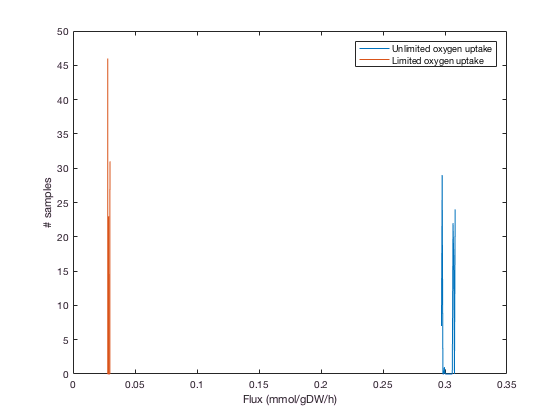

nbins = 20;
[yUn, xUn] = hist(X1_un(ibm, :), nbins);
[yLim, xLim] = hist(X1_lim(ibm, :), nbins);

f2 = figure;
plot(xUn, yUn, xLim, yLim);
legend('Unlimited oxygen uptake', 'Limited oxygen uptake')
xlabel('Flux (mmol/gDW/h)')
ylabel('# samples')

Undersampling results from selecting too small sampling parameters. The appropriate parameter values depend on the dimension of the polytope Ω defined by the model constraints (see intro). One rule of thumb says to set  $nSkip=8∗{dim\left(\Omega \right)}^2$ to ensure the statistical independence of samples. The random walk should be long enough to ensure convergence to a stationary sampling distribution [1].

options.nStepsPerPoint = 8 * size(P_lim.A, 2);
options.nPointsReturned = 1000;

This time, we can avoid the rounding step by inputting the rounded polytope from the previous round of sampling.

options.toRound = 0;
[~, X2_un] = sampleCbModel(unlimitedOx, [], [], options, P_un);

Generating samples...


[~, X2_lim] = sampleCbModel(limitedOx, [], [], options, P_lim);

Generating samples...


The converged sampling distributions for the ATP synthase reaction are much smoother, with a single peak at zero flux.

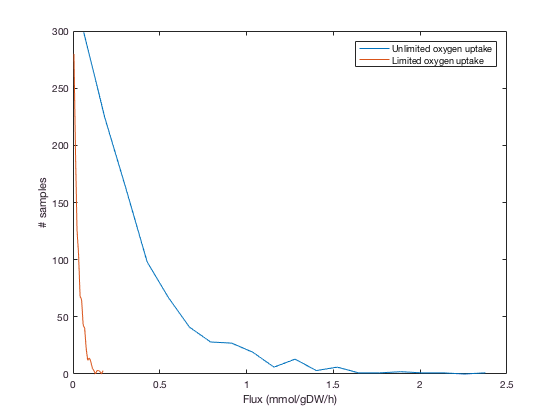

nbins = 20;
[yUn, xUn] = hist(X2_un(ibm, :), nbins);
[yLim, xLim] = hist(X2_lim(ibm, :), nbins);

f3 = figure;
p1 = plot(xUn, yUn, xLim, yLim);
legend('Unlimited oxygen uptake', 'Limited oxygen uptake')
xlabel('Flux (mmol/gDW/h)')
ylabel('# samples')

Adding the FVA results to the plot shows that the sampling distributions give more detailed information about the differences between the two models. In particular, we see that the flux minima and maxima are not equally probable. The number of samples from both the unlimitedOx and limitedOx models peaks at the minimum flux of zero, and decreases monotonically towards the maximum. It decreases more slowly in the unlimitedOx model, indicating that higher ATP production is more probable under unlimited oxygen uptake conditions. It is interesting to see that maximum ATP production is highly improbable in both models.

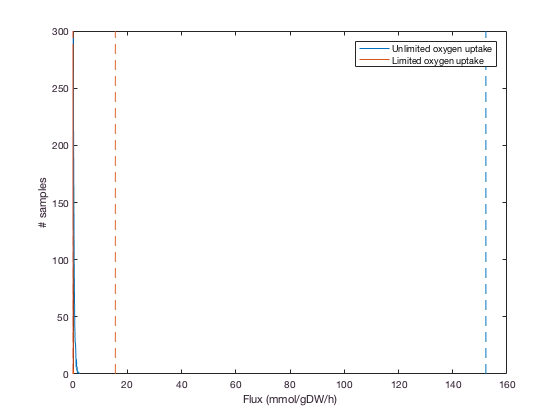

ylim = get(gca, 'ylim');
cUn = get(p1(1), 'color');
cLim = get(p1(2), 'color');

hold on
p2 = plot([minUn(ibm), minUn(ibm)], ylim, '--', [maxUn(ibm), maxUn(ibm)], ylim, '--');
set(p2,'color', cUn)
p3 = plot([minLim(ibm), minLim(ibm)], ylim, '--', [maxLim(ibm), maxLim(ibm)], ylim, '--');
set(p3, 'color', cLim)
hold off

Finally, plotting sampling distributions for six selected iPSC_dopa reactions shows how oxygen availability affects a variety of metabolic pathways.

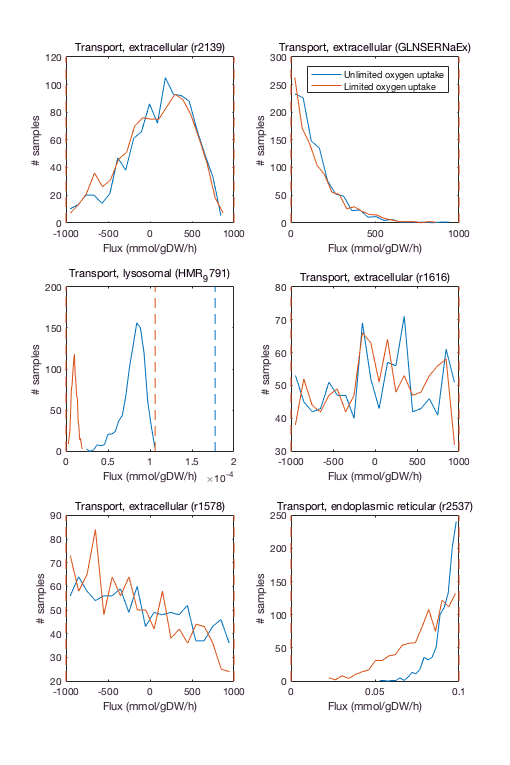

f4 = figure;
position = get(f4, 'position');
set(f4, 'units', 'centimeters', 'position', [position(1), position(2), 18, 27])

sampledRxns = {'r2139', 'GLNSERNaEx', 'HMR_9791', 'r1616', 'r1578', 'r2537'};
rxnsIdx = findRxnIDs(model, sampledRxns);

%ridx = randi(size(model.rxns,1), 1,6);

for i = rxnsIdx
    nbins = 20;
    [yUn, xUn] = hist(X2_un(i, :), nbins);
    [yLim, xLim] = hist(X2_lim(i, :), nbins);
    
    subplot(3, 2, find(rxnsIdx==i))
    h1 = plot(xUn, yUn, xLim, yLim);
    xlabel('Flux (mmol/gDW/h)')
    ylabel('# samples')
    title(sprintf('%s (%s)', model.subSystems{i}, model.rxns{i}), 'FontWeight', 'normal')
    
    if find(rxnsIdx==i)==2
        legend('Unlimited oxygen uptake', 'Limited oxygen uptake')
    end
    
    ylim = get(gca, 'ylim');
    
    hold on
    h2 = plot([minUn(i), minUn(i)], ylim, '--', [maxUn(i), maxUn(i)], ylim, '--');
    set(h2,'color',cUn)
    h3 = plot([minLim(i), minLim(i)], ylim, '--', [maxLim(i), maxLim(i)], ylim, '--');
    set(h3, 'color', cLim)
    hold off
end

## References

[1] Haraldsdóttir, H. S., Cousins, B., Thiele, I., Fleming, R.M.T., and Vempala, S. (2016). CHRR: coordinate hit-and-run with rounding for uniform sampling of constraint-based metabolic models. Submitted.

[2] Liliana...

[3] Orth, J. D., Thiele I., and Palsson, B. Ø. (2010). What is flux balance analysis? Nat. Biotechnol., 28(3), 245-248.

[4]  Zhang, Y. and Gao, L. (2001). On Numerical Solution of the Maximum Volume Ellipsoid Problem. SIAM J. Optimiz., 14(1), 53-76.

[5] Berbee, H. C. P., Boender, C. G. E., Rinnooy Ran, A. H. G., Scheffer, C. L., Smith, R. L., Telgen, J. (1987). Hit-and-run algorithms for the identification of nonredundant linear inequalities. Math. Programming, 37(2), 184-207.